file_path1 = 'C:\Users\gajapathy.s\Desktop\data_processing\imu\imu_sri.bag';

[time,o_w,o_x,o_y,o_z,a_x,a_y,a_z,l_x,l_y,l_z]= extract_bag(file_path1);
 time=time-time(1);
 time;

 [Yaw,Pitch,Roll]=Quaternions_to_euler(o_w,o_x,o_y,o_z)

Yaw =     4.7085    4.7084    4.7084    4.7089    4.7089    4.7089    4.7089    4.7089    4.7084    4.7099    4.7098    4.7097    4.7102    4.7106    4.7107    4.7102    4.7107    4.7102    4.7097    4.7092    4.7092    4.7082    4.7092    4.7082    4.7078    4.7072    4.7073    4.7074    4.7084    4.7083    4.7092    4.7092    4.7097    4.7102    4.7103    4.7093    4.7088    4.7078    4.7078    4.7078    4.7079    4.7089    4.7083    4.7073    4.7079    4.7099    4.7114    4.7109    4.7105    4.7105


Pitch =     0.6889    0.6879    0.6889    0.6894    0.6894    0.6884    0.6884    0.6884    0.6879    0.6885    0.6884    0.6883    0.6878    0.6883    0.6873    0.6868    0.6863    0.6858    0.6843    0.6847    0.6838    0.6836    0.6837    0.6827    0.6822    0.6827    0.6827    0.6818    0.6819    0.6828    0.6838    0.6828    0.6823    0.6829    0.6820    0.6820    0.6824    0.6823    0.6813    0.6813    0.6814    0.6814    0.6809    0.6817    0.6804    0.6806    0.6803    0.6807    0.6802    0.6803


Roll =    -2.1547   -2.1553   -2.1547   -2.1547   -2.1547   -2.1553   -2.1553   -2.1553   -2.1553   -2.1558   -2.1558   -2.1558   -2.1564   -2.1564   -2.1570   -2.1570   -2.1575   -2.1576   -2.1582   -2.1576   -2.1582   -2.1577   -2.1582   -2.1583   -2.1583   -2.1578   -2.1578   -2.1583   -2.1589   -2.1583   -2.1582   -2.1588   -2.1594   -2.1593   -2.1599   -2.1594   -2.1588   -2.1583   -2.1589   -2.1589   -2.1589   -2.1594   -2.1595   -2.1583   -2.1595   -2.1605   -2.1616   -2.1611   -2.1611   -2.1611


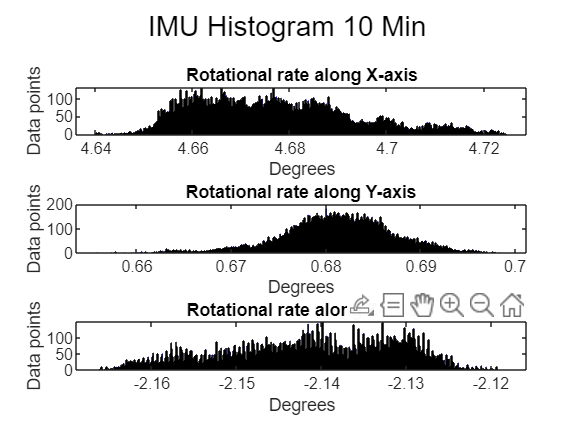


 figure
subplot(3,1,1)
histogram(Yaw, 500, 'FaceColor', 'b', 'EdgeColor', 'k')
title("Rotational rate along X-axis")
ylabel("Data points")
xlabel("Degrees")
subplot(3,1,2)
histogram(Pitch, 500, 'FaceColor', 'b', 'EdgeColor', 'k')
title("Rotational rate along Y-axis")
ylabel("Data points")
xlabel("Degrees")
subplot(3,1,3)
histogram(Roll, 500, 'FaceColor', 'b', 'EdgeColor', 'k')
title("Rotational rate along Z-axis")
ylabel("Data points")
xlabel("Degrees")

sgtitle('IMU Histogram 10 Min ')

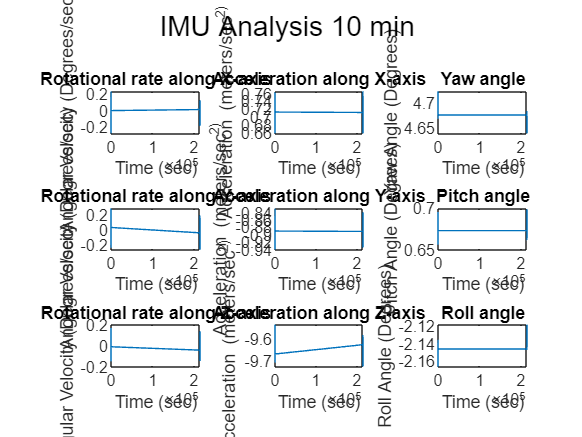


 figure
subplot(3,3,1)
plot(time, a_x)
title("Rotational rate along X-axis")
xlabel("Time (sec)")
ylabel("Angular Velocity (Degrees/sec)")

subplot(3,3,4)
plot(time, a_y)
title('Rotational rate along Y-axis')
xlabel("Time (sec)")
ylabel("Angular Velocity (Degrees/sec)")

subplot(3,3,7)
plot(time, a_z)
title('Rotational rate along Z-axis')
xlabel("Time (sec)")
ylabel("Angular Velocity (Degrees/sec)")



subplot(3,3,2)
plot(time, l_x)
title("Acceleration along X-axis")
xlabel("Time (sec)")
ylabel("Acceleration (meters/sec^2)")

subplot(3,3,5)
plot(time, l_y)
title("Acceleration along Y-axis")
xlabel("Time (sec)")
ylabel("Acceleration (meters/sec^2)")

subplot(3,3,8)
plot(time, l_z)
title("Acceleration along Z-axis")
xlabel("Time (sec)")
ylabel("Acceleration (meters/sec^2)")


subplot(3,3,3)
plot(time,Yaw)
title("Yaw angle")
xlabel("Time (sec)")
ylabel("Yaw Angle (Degrees)")

subplot(3,3,6)
plot(time, Pitch)
title("Pitch angle")
xlabel("Time (sec)")
ylabel("Pitch Angle (Degrees)")

subplot(3,3,9)
plot(time,Roll)
title("Roll angle")
xlabel("Time (sec)")
ylabel("Roll Angle (Degrees)")


sgtitle('IMU Analysis 10 min ')

function [Yaw, Pitch, Roll] = Quaternions_to_euler(o_w, o_x, o_y, o_z)

phi = atan2(2*(o_w.*o_x + o_y.*o_z), 1 - 2*(o_x.^2 + o_y.^2)); 
psi = -pi/2 + 2*atan2(sqrt(1 + 2*(o_w.*o_y - o_x.*o_z)), sqrt(1 - 2*(o_w.*o_y - o_x.*o_z))); 
theta = atan2(2*(o_w.*o_z + o_x.*o_y), 1 - 2*(o_y.^2 + o_z.^2));  

Yaw = phi.*(180/pi);
Pitch = psi.*(180/pi);
Roll = theta.*(180/pi);
end




function [time,o_w,o_x,o_y,o_z,a_x,a_y,a_z,l_x,l_y,l_z]= extract_bag(file_path1)


bag = rosbag(file_path1);
bSel = select(bag,'Topic','/imu');
msgStructs = readMessages(bSel,'DataFormat','struct');

len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;

for i=1:1:len
imuobj=msgStructs{i};

  t(i)=imuobj.Header.Stamp.Sec;
  ns(i)=imuobj.Header.Stamp.Nsec;
  nano_sec(i)=ns(i)*(1e-9);
  time(i)=t(i)+nano_sec(i);
  

 o_w(i)=imuobj.Imu.Orientation.W;
 o_x(i)=imuobj.Imu.Orientation.X;
 o_y(i)=imuobj.Imu.Orientation.Y;
 o_z(i)=imuobj.Imu.Orientation.Z;
 
 a_x(i)=(imuobj.Imu.AngularVelocity.X).*(180/pi);
 a_y(i)=(imuobj.Imu.AngularVelocity.Y).*(180/pi);
 a_z(i)=(imuobj.Imu.AngularVelocity.Z).*(180/pi);
 
 l_x(i)=imuobj.Imu.LinearAcceleration.X;
 l_y(i)=imuobj.Imu.LinearAcceleration.Y;
 l_z(i)=imuobj.Imu.LinearAcceleration.Z;


end

end
























































